% Path to the code/scripts
addpath(genpath('/Users/teatompos/Documents/GitHub/PhD_Project1--small-spiking-neural-network'))
addpath(genpath('/Users/teatompos/Desktop/Matlab_scripts/RU_1st_internship_Neurophysiology_Dept/DynaSim'))
clear all

% Saving names prefixes

SaveSim_pre = 'Fig2_Net_';
SaveAn_pre = 'Fig2_Analysis_';
SaveFig_pre = 'Fig2_';

% Path to save/retrieve results
ResultsPath = '/Volumes/T7/Data/Fixed_CTXseed';
addpath(genpath(ResultsPath))

Simulate = 0;
SaveResults = 1;

cd(ResultsPath)

fileNames = dir;
fileIdx = cell2mat(cellfun(@(x) startsWith(x,SaveSim_pre), {fileNames.name}, 'uniformoutput', false))';
fileNamesExist = {fileNames(fileIdx).name}';

% Path to save/retrieve analysis
AnalysisPath = '/Volumes/T7/Data/Fixed_CTXseed_analysis';
addpath(genpath(AnalysisPath))

BasicAnalysis = 0;
AdvancedAnalysis = 0;

SaveAnalysis = 1;

% Path to save figures
FiguresPath = '/Users/teatompos/Library/CloudStorage/GoogleDrive-t.tompos@neurophysiology.nl/.shortcut-targets-by-id/1f3yqxuDDFP_-nrGlSKbqcVC3RJJZZWTiWyK5Kl5x65maOi21i1OEIloSOR_UsCfsdiH2FbZf/Lab notebook Tea Tompoš/Thesis/Chapter 2 (The model)/Figures/Fig2_Fig3';
addpath(genpath(FiguresPath))

SaveFigures = 1;

% Scaling factors
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

% E-I ratio
Ecells_percentage = 0.85;
Icells_percentage = 0.15;

% Simulation time
tstop = 600;

% LIF neurons?
isLif = 0;

% Which seeds to use?
RandomSeeds = [4, 47, 49, 67, 30];
seeds = [];

% Repetition per seed
repetitions = 10;

if Simulate
    % limit the number of parallel workers because matlab runs out of memory
    delete(gcp('nocreate'))
    parpool('local', 6);
end

cd(ResultsPath)

% Stimulate the same network with varying thalamic input

if Simulate
    for s_num = RandomSeeds(3)
        seeds.ctx_seed = s_num; % this will fix cortical connectivity
        seeds.vpm_seed = []; % this will let vpm vary across repetitions

        parfor synStr = 1:length(synScalingFactors)
            for pconn = 1:length(pconnScalingFactors)
                synParams = struct('synstr',[synScalingFactors(synStr) synScalingFactors(synStr)], ...
                    'pconn', [pconnScalingFactors(pconn) pconnScalingFactors(pconn)]);

                for r_num = 1:repetitions
                    NetSaveName = sprintf('%s_S%i_P%i_Rep%i_Seed%i', SaveSim_pre, round(synScalingFactors(synStr)*100), round(pconnScalingFactors(pconn)*100), r_num, s_num);
                    SpikingNetwork = SimN4(Ecells_percentage, Icells_percentage, [], synParams, [], [], 'synthetic', seeds, tstop);
                    SpikingNetwork.Seeds = seeds;
                    fprintf('Simulated %s. \n', NetSaveName)
                    
                    if SaveResults
                        cd(ResultsPath)
                        ParallelSave(NetSaveName,SpikingNetwork)
                    end

                end
            end
        end
    end
end

% Basic analysis
s_num = RandomSeeds(3);

if BasicAnalysis
    % activate paralel cores
    delete(gcp('nocreate'))
    myCluster = parcluster('local');
    delete(myCluster.Jobs);
    parpool('local', 8);
    
    % save stuff here
    cd(AnalysisPath)
    
    % check if there is already something analysed
    fileNames = dir;
    fileIdx = cell2mat(cellfun(@(x) contains(x,['_Seed' num2str(s_num) '_backup']), {fileNames.name}, 'uniformoutput', false))';
    analysisNameExist = {fileNames(fileIdx).name}';
    
    for synStr = 1:length(synScalingFactors)
        failedStuff = [];
        newAn = 0;
    
        loadLabel = [SaveAn_pre '_S' num2str(round(synScalingFactors(synStr)*100)) '_'];
        if any(contains(analysisNameExist, loadLabel))
            fullLoadLabel = cell2mat(analysisNameExist(find(contains(analysisNameExist, loadLabel))));
    %         loadedData = ParallelLoad(fullLoadLabel);
            loadedData = load(fullLoadLabel);
            SNN_analysed = loadedData.SNN_analysed;
        else
            SNN_analysed = [];
        end
    
        for pconn = 1:length(pconnScalingFactors)
            for r_num = 1:repetitions
                NetSaveName = sprintf('%s_S%i_P%i_Rep%i_Seed%i', SaveSim_pre, round(synScalingFactors(synStr)*100), round(pconnScalingFactors(pconn)*100), r_num, s_num);
                try
                    if ~isempty(SNN_analysed) % check if something was already analysed
                        if ~any(contains(SNN_analysed.SimulationLabel, NetSaveName))
                            newAn = 1;
                        else
                            fprintf('Already analysed %s. \n', NetSaveName)
                        end
                    else % if SNN is empty
                        newAn = 1;
                    end
    
                    if newAn
                        fprintf('Loading %s. \n', NetSaveName)
    %                     loadedData = ParallelLoad(NetSaveName);
                        loadedData = load(NetSaveName);
                        SpikingNetwork = loadedData.SpikingNetwork;
    
                        SNN_analysed = [SNN_analysed; analyzeSparseSim(SpikingNetwork, NetSaveName)];
                        fprintf('Analysed %s. \n', NetSaveName)
    
                        % inermediate save
                        cd(AnalysisPath)
                        AnSaveName = sprintf('%s_S%i_Seed%i_backup', SaveAn_pre, round(synScalingFactors(synStr)*100), s_num);
    %                     ParallelSave(AnSaveName,SNN_analysed)
                        save(AnSaveName, 'SNN_analysed','-v7.3')
                    end
                    newAn = 0;
                catch ME
                    failedStuff{end+1,1} = NetSaveName;
                    failedStuff{end,2} = ME.message;
                end
            end
        end
        if SaveAnalysis
            cd(AnalysisPath)
            AnSaveName = sprintf('%s_S%i_Seed%i_full', SaveAn_pre, round(synScalingFactors(synStr)*100), s_num);
            save(AnSaveName, 'SNN_analysed','-v7.3')
        
            fprintf('Saved the following analysis: %s.\n', AnSaveName)
        end
        failedStuff
    end
end

% Advanced analysis
clearvars -except s_num synScalingFactors pconnScalingFactors Save* RandomSeeds AnalysisPath AdvancedAnalysis FiguresPath

if ~exist('s_num','var')
    s_num = RandomSeeds(3);
end

warning('off')

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];

cd(AnalysisPath)

%this used to be function fitting  protocol but we abandoned it
if AdvancedAnalysis
    for synStr = synScalingFactors
        AnSaveName = sprintf('%s_S%i_Seed%i_full.mat', SaveAn_pre, round(synStr*100), s_num);
        load(AnSaveName)
        
        quant = [];
        for pconn = pconnScalingFactors
            for jj=1:length(pops)
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = SNN_analysed(strcmp(SNN_analysed.Population, pops(jj,:)) & contains(SNN_analysed.SimulationLabel, label),:);

                if ~isempty(tbl)
                    AllSim_AllEvents = []; % this will collect data for all events in one simulation
                    AllSim_PopXCorr = [];
                    noActivity = 0;
                    eventCount = 1;
                    for simNum = 1:size(tbl,1)
                        AllSim_PopXCorr(simNum,1).SimulationLabel = tbl.SimulationLabel{simNum, 1};
                        AllSim_PopXCorr(simNum,1).PopulationPSTH_XCorr = tbl.PopulationPSTH_XCorr{simNum,1};
                        AllSim_PopXCorr(simNum,1).PopulationPSTH_XCorrLags_inMs = tbl.PopulationPSTH_XCorrLags{simNum,1} * tbl.PSTHBinSize{simNum,1};
                        
                        for evNum = 1:length(tbl.VPMEventData{simNum,1})
                            AllSim_AllEvents(eventCount,1).SimulationLabel = tbl.SimulationLabel{simNum, 1};
                            
                            % look into events
                            binSize_events = tbl.PSTHBinSize{simNum, 1};
                            eventLength = 60/binSize_events;
                            pre_event = tbl.VPMEventData{simNum,1}{1, evNum}.StartTime;
                            peak_event = tbl.VPMEventData{simNum,1}{1, evNum}.PeakTime;
                            post_event = tbl.VPMEventData{simNum,1}{1, evNum}.EndTime;
                                                        
                            %% MAKE A HISTOGRAM
                            event_time_vec_precise = peak_event:binSize_events:post_event; % this one starts when the event time starts, not with the left edge
                            vpm_hist = histcounts(cell2mat(tbl.VPMEventData{simNum,1}{1, evNum}.VPMSpikes'), event_time_vec_precise);
                            ctx_hist = histcounts(cell2mat(tbl.VPMEventData{simNum,1}{1, evNum}.CTXTime'), event_time_vec_precise);
                            
                            if length(ctx_hist) < eventLength
                                % i pad only at the right side because all
                                % events start from the event peak; this
                                % means that it can not be too short on the
                                % left side
                                vpm_hist = [vpm_hist zeros([1 diff([length(vpm_hist) eventLength])])];
                                ctx_hist = [ctx_hist zeros([1 diff([length(ctx_hist) eventLength])])];
                            end
                            x_vec = ([0:length(ctx_hist)])*binSize_events;
                            
                            active_VPM = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{simNum,1}{1, evNum}.VPMSpikes, 'uniformoutput', 0)));
                            FR_VPM = vpm_hist ./ active_VPM;
                            
                            AllSim_AllEvents(eventCount,1).VPM_hist = vpm_hist;
                            AllSim_AllEvents(eventCount,1).VPM_participating = active_VPM;
                            AllSim_AllEvents(eventCount,1).VPM_FR_participating = FR_VPM;
                            AllSim_AllEvents(eventCount,1).hist_time = x_vec;
                                
                            active_CTX = sum(cell2mat(cellfun(@(x) ~isempty(x), tbl.VPMEventData{simNum,1}{1, evNum}.CTXTime, 'uniformoutput', 0)));
                            
                            if any(ctx_hist>0)
                                %% GET FR 
                                FR_participating = ctx_hist ./ active_CTX; % new formula: FR = #spikes / N
                                FR_participating(isnan(FR_participating)) = 0;
                                
                                AllSim_AllEvents(eventCount,1).CTX_hist = ctx_hist;
                                AllSim_AllEvents(eventCount,1).CTX_participating = active_CTX;
                                AllSim_AllEvents(eventCount,1).CTX_FR_participating = FR_participating;
                                
                                %% GET TOTAL SPIKING ACTIVITY (INTEGRATE THE SIGNAL)
                                tot_spikes_participating = trapz(FR_participating);
                                
                                AllSim_AllEvents(eventCount,1).CTX_FR_participating_AUC = tot_spikes_participating;
                            else
                                noActivity = noActivity + 1;
                            end
                            eventCount = eventCount + 1;
                        end                 
                    end
                end
                quant = [quant; table({pops(jj,:)},{synStr},{pconn},{label},{AllSim_AllEvents},{AllSim_PopXCorr},'VariableNames',{'Population', 'SynStr', 'PConn', 'SimulationLabel', 'EventData', 'XCorrData'})];
            end
        end
        if SaveAnalysis
            save(sprintf('%s_S%i_EventData', SaveAn_pre, round(synStr*100)), 'quant','-v7.3')
        end
    end
end

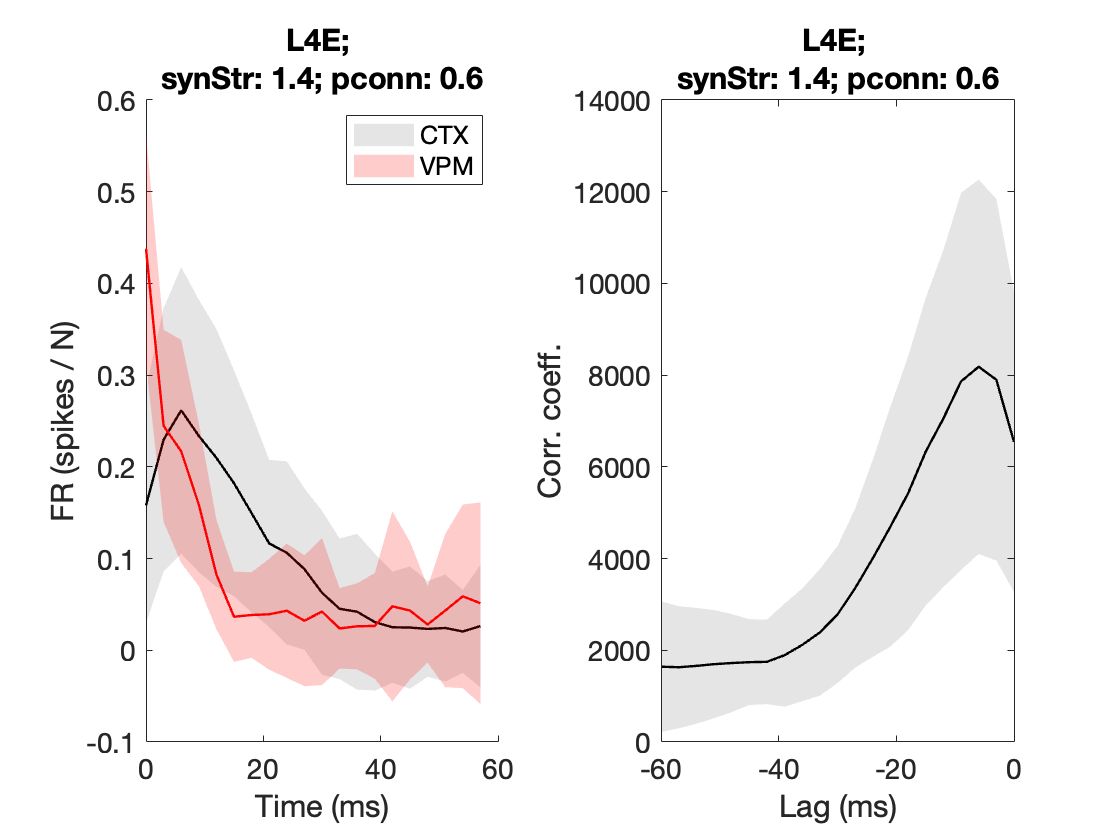

% example analysis
figure; clf; tiledlayout(1,2);

synStr = 1.4;
pconn = 0.6;
pop = 'L4E';

load(sprintf('%s_S%i_EventData.mat', SaveAn_pre, round(synStr*100)))
label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
tbl = quant(strcmp(quant.Population, pop) & contains(quant.SimulationLabel, label),:);

% AUC normalized to max AUC
nexttile; hold on;
signal = cell2mat({tbl.EventData{1,1}.CTX_FR_participating}');
stdShade(signal, 0.1, 'k', tbl.EventData{1,1}(1).hist_time(1:end-1))

% AUC nomalized to VPM_AUC
vpm_signal = cell2mat({tbl.EventData{1,1}.VPM_FR_participating}');
stdShade(vpm_signal, 0.2, 'r', tbl.EventData{1,1}(1).hist_time(1:end-1))
xlabel('Time (ms)')
ylabel('FR (spikes / N)')
set(gca, 'fontsize', 14)
title(sprintf('%s; \nsynStr: %.1f; pconn: %.1f', pop, synStr, pconn))
ax=get(gca,'Children');
legend(ax([4 2]),'CTX', 'VPM')

% max XCorr nomaliyed to max of all XCorr
nexttile;
leftEdge = nearest(tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs,-60);
rightEdge = nearest(tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs,0);
                    
leftSideXCorr = cell2mat(arrayfun(@(x) tbl.XCorrData{1,1}(x).PopulationPSTH_XCorr(1,leftEdge:rightEdge), 1:size(tbl.XCorrData{1,1},1), 'uniformoutput',0)');
stdShade(leftSideXCorr, 0.1, 'k', tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs(1,leftEdge:rightEdge));
xlabel('Lag (ms)')
ylabel('Corr. coeff.')
set(gca, 'fontsize', 14)
title(sprintf('%s; \nsynStr: %.1f; pconn: %.1f', pop, synStr, pconn))

if SaveFigures
    cd(FiguresPath)
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_analysisExample_seed' num2str(s_num)], '-dpdf','-bestfit')
end

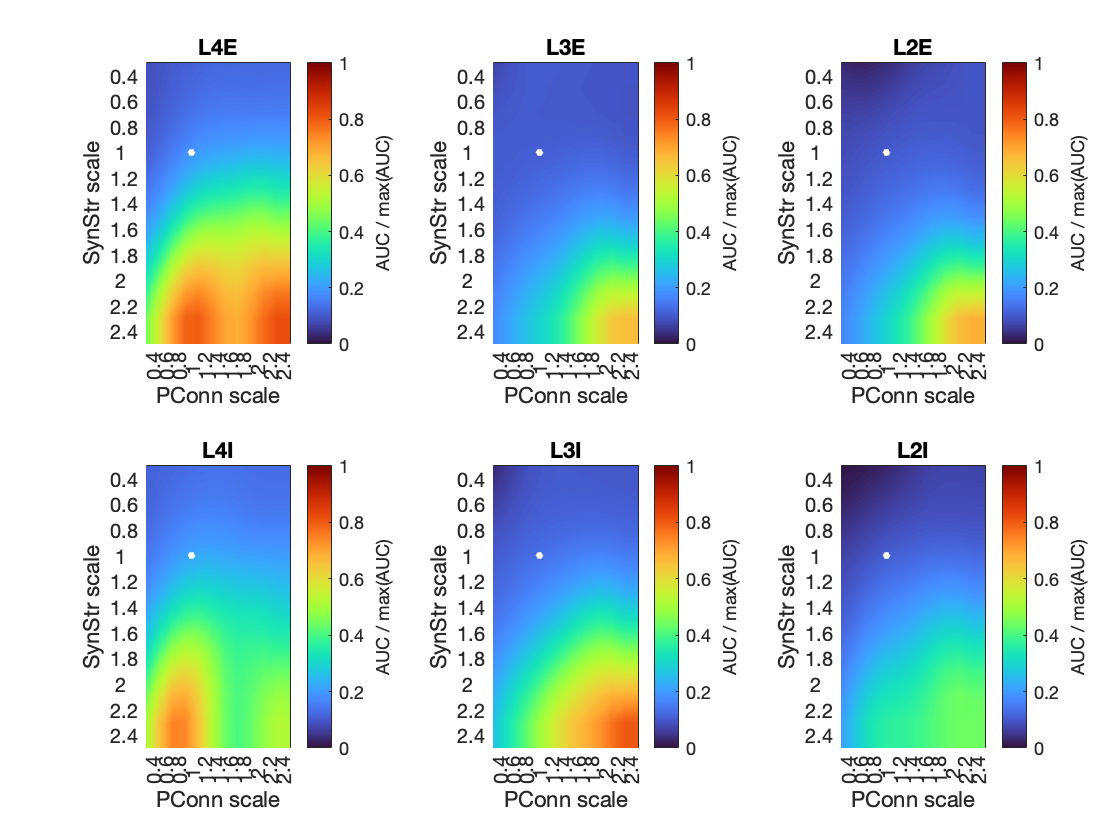

% Make Figure 2
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotDataAUC.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData.mat', SaveAn_pre, round(synStr*100)))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                
                if any(contains(fieldnames(tbl.EventData{1,1}), 'CTX_FR_participating'))
                    dataPoints = trapz(nanmean(cell2mat({tbl.EventData{1,1}.CTX_FR_participating}'),1));
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
            end
        end
        plotDataFlat = cell2mat(plotData);

        Fig2_PlotData{popSeq} = plotDataFlat;
        
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, imgaussfilt(plotDataFlat, 1.5));
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'interp');
    set(gca,'ydir','reverse')
    cb = colorbar;
    colormap(turbo(256));
    caxis([0, 1]);
    title(pop)
    ylabel(cb,'AUC / max(AUC)', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotDataAUC', 'Fig2_PlotData','-v7.3')
end

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on; scatter(1,1,14,'filled','markerfacecolor',[1 1 1],'markeredgecolor','none'); end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_TotSpikes_seed' num2str(s_num)], '-dpdf','-bestfit')
end

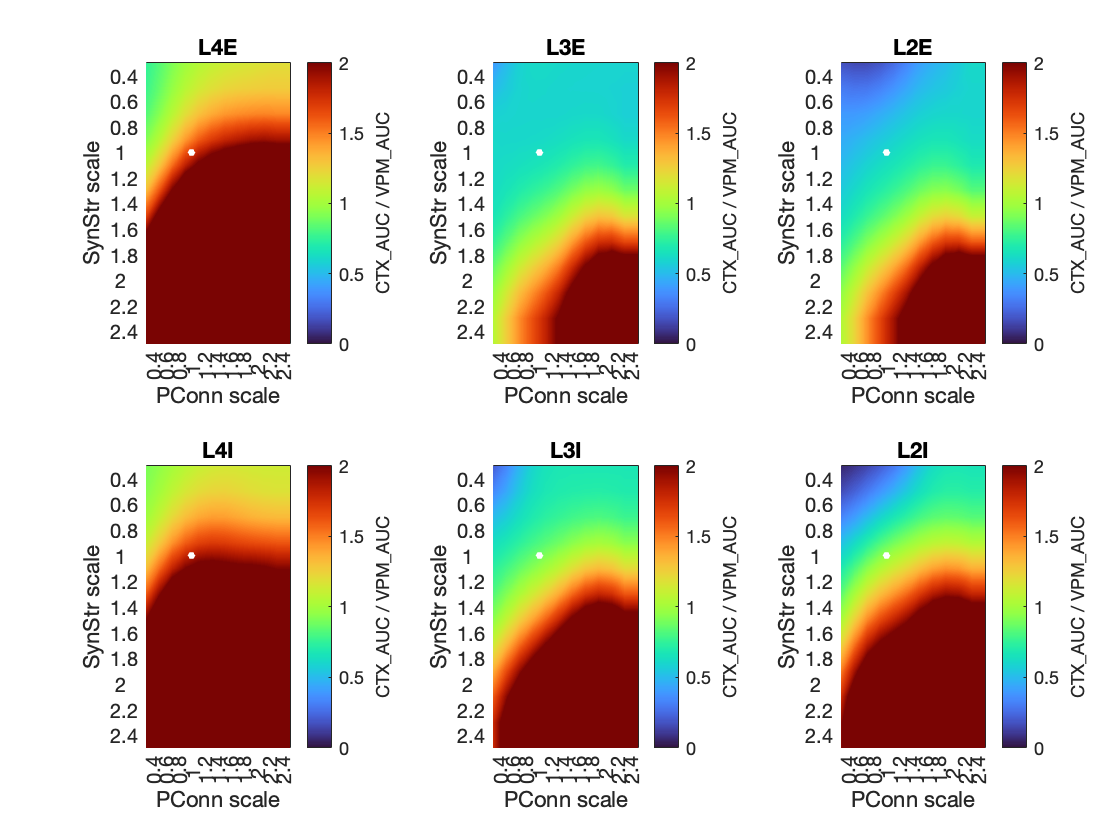

% Make Figure 2
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotData_normToVPM.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    VPM_data = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData.mat', SaveAn_pre, round(synStr*100)))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                allVPM_AUC = trapz(nanmean(cell2mat({tbl.EventData{1,1}.VPM_FR_participating}'),1));
                
                if any(contains(fieldnames(tbl.EventData{1,1}), 'CTX_FR_participating'))
                    dataPoints = trapz(nanmean(cell2mat({tbl.EventData{1,1}.CTX_FR_participating}'),1));
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
                VPM_data{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = allVPM_AUC;
            end
        end
        plotDataFlat = cell2mat(plotData);
        VPM_data_flat = cell2mat(VPM_data);

        Fig2_PlotData{1,popSeq} = plotDataFlat;
        Fig2_PlotData{2,popSeq} = VPM_data_flat;
        
        plotDataFlat = plotDataFlat./VPM_data_flat; % normalize to the vpm auc;
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        VPM_data_flat = Fig2_PlotData{2, popSeq};
        
        plotDataFlat = plotDataFlat./VPM_data_flat; % normalize to the max;
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, imgaussfilt(plotDataFlat, 1.5));
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'interp');
    set(gca,'ydir','reverse')
    cb = colorbar;
    colormap(turbo(256));
    caxis([0, 2]);
    title(pop)
    ylabel(cb,'CTX_AUC / VPM_AUC', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotData_normToVPM', 'Fig2_PlotData','-v7.3')
end

% nexttile(1); caxis([0 1])
% nexttile(4); caxis([0 1])

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on; scatter(1,1,14,'filled','markerfacecolor',[1 1 1],'markeredgecolor','none'); end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_TotSpikes_normToVPM_seed' num2str(s_num)], '-dpdf','-bestfit')
end

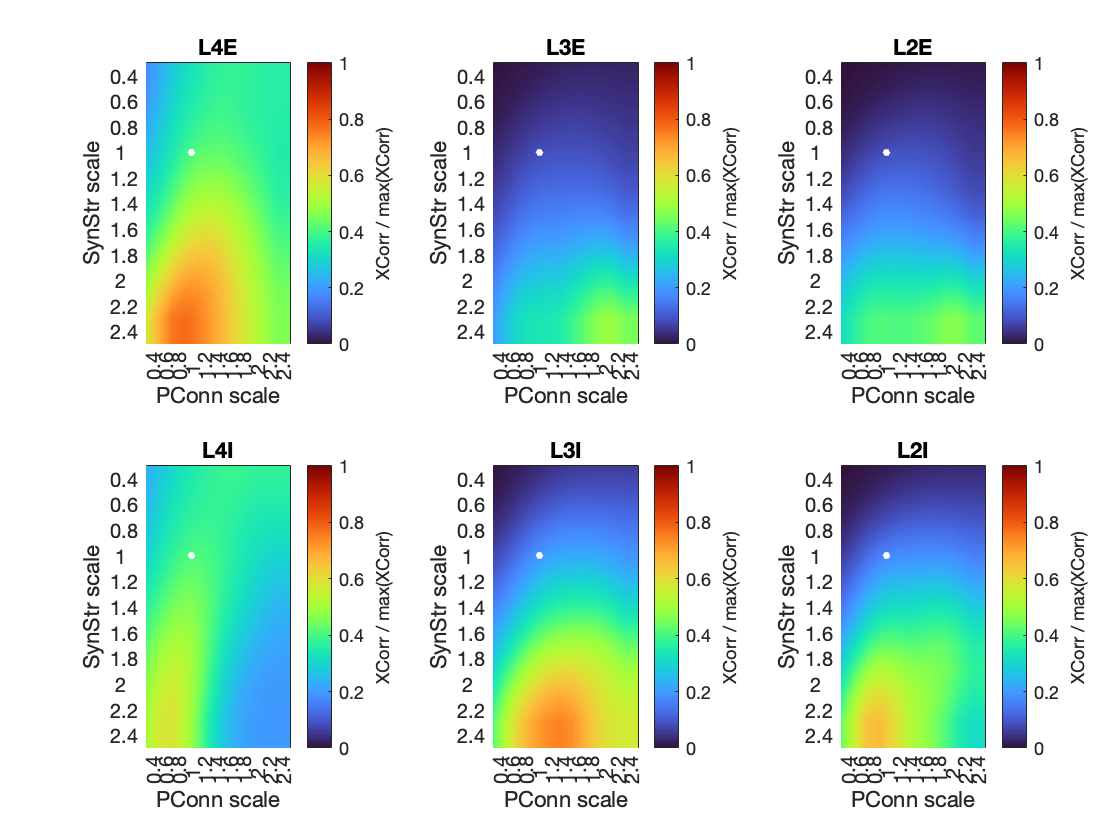

% Make Figure 2
clearvars -except s_num SaveFigures SaveAn_pre SaveFig_pre FiguresPath pops s_num SaveSim_pre AnalysisPath

pops = ['L2E';'L2I';'L3E';'L3I';'L4E';'L4I'];
synScalingFactors = [0.4:0.2:2.5];
pconnScalingFactors = [0.4:0.2:2.5];

figure(1); clf; tiledlayout(2,3)
cd(AnalysisPath)

popSequence = [5 3 1 6 4 2];
newAnalysis = 0;

if newAnalysis
    Fig2_PlotData = [];
    saveNew = 1;
else
    load('Fig2_PlotData_XCorr.mat')
    saveNew = 0;
end

for popSeq = 1:length(popSequence)
    jj = popSequence(popSeq);
    plotData = [];
    pop = pops(jj,:);

    if newAnalysis
        for synStr = synScalingFactors
            load(sprintf('%s_S%i_EventData.mat', SaveAn_pre, round(synStr*100)))
            
            for pconn = pconnScalingFactors
                label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
                tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
                dataPoints = [];
                
                if any(contains(fieldnames(tbl.XCorrData{1,1}), 'PopulationPSTH_XCorr'))
                    leftEdge = nearest(tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs,-60);
                    rightEdge = nearest(tbl.XCorrData{1,1}(1).PopulationPSTH_XCorrLags_inMs,0);
                    
                    leftSideXCorr = cell2mat(arrayfun(@(x) tbl.XCorrData{1,1}(x).PopulationPSTH_XCorr(1,leftEdge:rightEdge), 1:size(tbl.XCorrData{1,1},1), 'uniformoutput',0)');
                    dataPoints = max(nanmean(leftSideXCorr));
                else
                    dataPoints = NaN;
                end
                plotData{find(synScalingFactors==synStr),find(pconnScalingFactors==pconn)} = dataPoints;
            end
        end
        plotDataFlat = cell2mat(plotData);

        Fig2_PlotData{1,popSeq} = plotDataFlat;
        
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the vpm auc;
    else
        plotDataFlat = Fig2_PlotData{1, popSeq};
        
        plotDataFlat = plotDataFlat./max(max(plotDataFlat)); % normalize to the max;
    end
  
    plotDataFlat(isnan(plotDataFlat)) = 0;
    
    %%% TOTAL SPIKING
    nexttile(popSeq);
    h = pcolor_fleur(pconnScalingFactors, synScalingFactors, imgaussfilt(plotDataFlat,1.5));
    set(h, 'EdgeColor', 'none', 'AlphaData', ~isnan(plotDataFlat), 'facecolor', 'interp');
    set(gca,'ydir','reverse')
    cb = colorbar;
    colormap(turbo(256));
    caxis([0, 1]);
    title(pop)
    ylabel(cb,'XCorr / max(XCorr)', 'Interpreter','none')

    xax = gca;
    xax.XTickMode = 'manual';
    xax.XTick = pconnScalingFactors;
    xax.XTickLabel = pconnScalingFactors;

    xax.YTickMode = 'manual';
    xax.YTick = synScalingFactors;
    xax.YTickLabel = synScalingFactors;
    xlabel('PConn scale')
    ylabel('SynStr scale')
end
if saveNew
    cd(AnalysisPath); save('Fig2_PlotData_XCorr', 'Fig2_PlotData','-v7.3')
end

% nexttile(1); caxis([0 1])
% nexttile(4); caxis([0 1])

if SaveFigures
    cd(FiguresPath)
    for ii=1:6; nexttile(ii); hold on; scatter(1,1,14,'filled','markerfacecolor',[1 1 1],'markeredgecolor','none'); end
    f=gcf;
    set(f, 'paperorientation', 'landscape', 'renderer','painter')
    print(f,[SaveFig_pre '_heatmap_TotSpikes_PeakXCorr_seed' num2str(s_num)], '-dpdf','-bestfit')
end

# Some helper code

% intermediate exploration
figure; tiledlayout(11,11)

jj = 5;
plotData = [];
pop = pops(jj,:);

for synStr = synScalingFactors
    load(sprintf('%s_S%i_EventFunctionFitting.mat', SaveAn_pre, round(synStr*100)))
    
    for pconn = pconnScalingFactors
        label = sprintf('%s_S%i_P%i_Rep', SaveSim_pre, round(synStr*100), round(pconn*100));
        tbl = quant(strcmp(quant.Population, pops(jj,:)) & contains(quant.SimulationLabel, label),:);
        if ~isempty(tbl.EventFitting{1,1})
            if any(contains({tbl.EventFitting{1,1}.SimulationLabel}', 'Combined'))
                signal = tbl.EventFitting{1,1}(end).FR_participating;
                time = tbl.EventFitting{1,1}(end).FR_participating_time(1:end-1);
                
                nexttile;
                stdShade(signal, 0.2, 'k', time)
                title(sprintf('S%i_P%i', round(synStr*100), round(pconn*100)), 'Interpreter', 'none')
                ylim([0 400])
            else
                nexttile;
                title(sprintf('S%i_P%i', round(synStr*100), round(pconn*100)), 'Interpreter', 'none')
                ylim([0 400])
            end
        else
            nexttile;
            title(sprintf('S%i_P%i', round(synStr*100), round(pconn*100)), 'Interpreter', 'none')
            ylim([0 400])
        end
    end
end

return

% This code inspects individual networks
clear SpikingNetwork inspection pop

synStr = 2;
pconn = 1.2;
r_num = 6;
NetSaveName = sprintf('%s_S%i_P%i_Rep%i_Seed%i', SaveSim_pre, round(synStr*100), round(pconn*100), r_num, s_num);
load(NetSaveName)
fprintf('Loaded %s.mat\n', NetSaveName)

pop = 'L4I';
inspection = inspectCellBehaviour(SpikingNetwork, pop, [0 0], []);

fns_idx = inspection.cell_idx{1}
fs_idx = inspection.cell_idx{2}

figure; clf; hold on;
for ii = 1:size(SpikingNetwork.([pop '_V']),2)
    yIncrement = ii * 80;
    if ismember(ii, [fns_idx, fs_idx])
        plot(SpikingNetwork.time, SpikingNetwork.([pop '_V'])(:,ii) + yIncrement, 'r')
    else
        plot(SpikingNetwork.time, SpikingNetwork.([pop '_V'])(:,ii) + yIncrement, 'k')
    end
end
plot([100 100], ylim, ':r', 'linewidth', 2)
ylabel('Neurons (stacked)')
xlabel('Time (ms)')
set(gca, 'fontsize', 14, 'yticklabel',[])
title(['Activity of ' pop ' in ' NetSaveName '.'], 'interpreter', 'none')

SNN_indivitual = analyzeSim(SpikingNetwork, NetSaveName, 0, 'threshold');
fprintf('Nans detected: %i.\n', size(SpikingNetwork.([pop '_V']),2)-sum([numel(fns_idx) numel(fs_idx) numel(inspection.cell_idx{3})]))

figure; clf; hold on;
bar(1,numel(fns_idx),'EdgeColor','none', 'facecolor','k','facealpha',0.1)
bar(2,numel(fs_idx),'EdgeColor','none', 'facecolor','b','facealpha',0.2)
bar(3,numel(inspection.cell_idx{3}),'EdgeColor','none', 'facecolor','g','facealpha',0.2)
set(gca,'fontsize',16, 'xticklabel', [])
legend('FNS', 'FS', 'HT', 'location', 'northwest')
ylabel('Cell count')